# Anello di corrente

La funzione di trasferimento che lega $V_{a\;} \;a\;I_a$ abbiamo visto essere


$${\textrm{tf}}_{\textrm{VI},\textrm{complete}} =G\left(s\right)=\frac{\frac{\tau {\;}_m \;}{R_a }s}{\tau_m \tau {\;}_e s^2 +\tau {\;}_m s+1}$$


Volendo andare ad applicare un regolatore di tipo **PI** (**Proporzionale - Integrale**), andremo ad inserire il seguente blocco regolatore


$$\begin{array}{l}
R_{\textrm{PI}} \left(s\right)=K_P +\frac{K_I }{s}=K_{P\;} \left(1+\frac{K_I }{K_P s}\right)\to \tau {\;}_I =\frac{K_P }{K_I }\\
\to \;=K_P \left(1+\frac{1}{\tau {\;}_i s}\right)=K_P \left(\frac{1+\tau {\;}_i s}{\tau {\;}_i s}\right)=K_P \bullet \frac{K_I }{K_P }\left(\frac{1+\tau_{i\;} s}{s}\right)=k_{g{\;}_i } \left(\frac{1+s\tau {\;}_i }{s\tau {\;}_i }\right)
\end{array}$$


Considerando $t_m >>4*\tau {\;}_e$ (assunzione effettivamente verificata per il modello del motore utilizzato) andiamo a lavorare con la funzione di trasferimento semplificata, che considera solamente la dinamica elettrica del motore, tralasciando quella meccanica: questo ci permette di effettuare delle semplificazioni sulla stesura del regolatore.

function currentLoop = CurrentLoop(m, showBode, Ts)
    s = tf('s');

Fissiamo la frequenza critica a $1\textrm{KHz}$, ovvero la frequenza per cui il diagramma di Bode della risposta in frequenza presenta modulo in *db* pari a zero, ovvero $\left|L\left(s\right)\right|=1$(guadagno unitario).

    f_c = 1000;
    w_c = 2 * pi * f_c;

Considerando la funzione di trasferimento semplificata


$${\textrm{tf}}_{\textrm{VI},\textrm{simple}} =G\left(s\right)=\frac{1}{R_{a\;} }\bullet \frac{1}{\;1+s\tau_e }$$


e aggiungendo il controllore PI, si ottiene il seguente sistema retroazionato

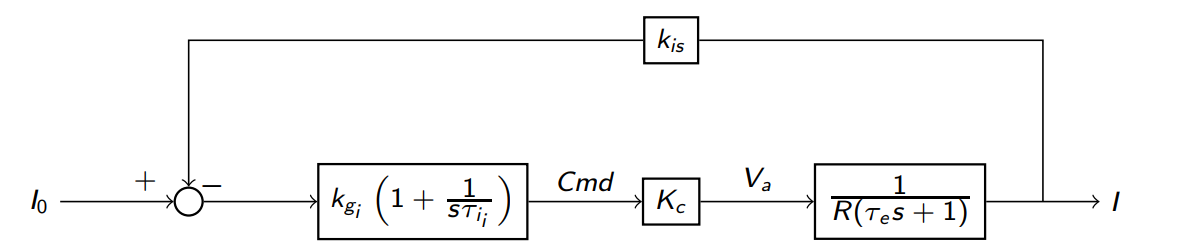

Si lavora quindi sulla funzione di trasferimento di andata, cercando di andare ad eliminare il polo elettrico $\left(1+\tau {\;}_e s\right)$ con lo zero del regolatore e imponendo guadagno unitario in corrispondenza della funzione critica.

Questo ci porta a definire


$$k_{g_i } =2\pi \;f_{c\;} \tau {\;}_e R_a =\omega {\;}_c \tau {\;}_e R_a$$


    K_gi = w_c * m.te * m.Ra;

Regolatore di corrente proporzionale integrativo (PI):

    PI_I = K_gi * tf([m.te,1],[m.te, 0]);
    PI_I_d = c2d(PI_I,Ts,'tustin')

Risposta in anello chiuso del sistema semplificato

    tf_V_I_simple = m.tf_V_I_simple;
    H_I_simple = feedback(PI_I*tf_V_I_simple,1);

Per completezza riportiamo anche la funzione di trasferimento in anello chiuso del sistema completo, ovvero considerando anche la dinamica meccanica, nel caso in cui l'assunzione $\tau {\;}_{m\;} >>4*\tau {\;}_e$ venga meno.

    H_I = feedback(PI_I*m.tf_V_I,1);

Plottiamo i diagrammi di bode per poterne confrontare la risposta e la bonta delle semplificazione tramite il solo modello elettrico:

    if showBode == 1
        figure('Name', 'Modello motore con anello corrente');
        h = bodeplot(H_I_simple);
        hold on;
        bodeplot(H_I);
        grid on;
        setoptions(h,'FreqUnits','Hz');
        legend('Modello semplificato','Modello completo');
        hold off
    end

Salvataggio dei parametri di interesse nella struttura in uscita.

    currentLoop.f_c = f_c;
    currentLoop.w_c = w_c;
    currentLoop.Kgi = K_gi;
    currentLoop.PI_regulator = PI_I;
    currentLoop.PI_regulator_discrete = PI_I_d;
    currentLoop.H_I = H_I;
    currentLoop.H_I_simple = H_I_simple;
end